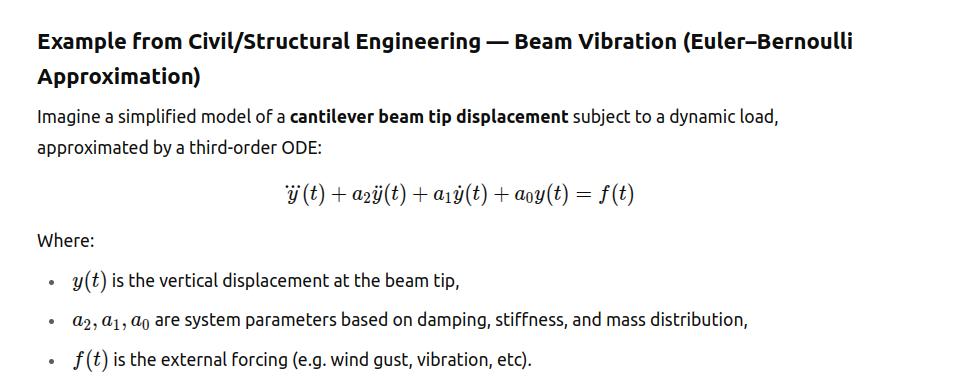

### 1. Formulate the model (the third-order ODE) as a system of three first-order ODEs

### 2. Implement the rate function

For specific values for the constants

function dxdt = beam_odes(t, x)
    a2 = 6;
    a1 = 2;
    a0 = 6;
    f = 0;
    dxdt = zeros(3,1);
    dxdt(1) = x(2);
    dxdt(2) = x(3);
    dxdt(3) = -a2*x(3)-a1*x(2)-a0*x(1)+f;
    % Enforce a column
    dxdt = dxdt(:);
end

### 3. Use the solver to numerically approximate the solution

Initial condition

x0 = [0.1 0 0];
tspan = [0 100];
[tt, xx] = ode45(@beam_odes, tspan, x0)

tt =          0
    0.0001
    0.0002
    0.0003
    0.0003
    0.0008
    0.0012
    0.0016
    0.0020
    0.0041


xx =     0.1000         0         0
    0.1000   -0.0000   -0.0001
    0.1000   -0.0000   -0.0001
    0.1000   -0.0000   -0.0002
    0.1000   -0.0000   -0.0002
    0.1000   -0.0000   -0.0005
    0.1000   -0.0000   -0.0007
    0.1000   -0.0000   -0.0009
    0.1000   -0.0000   -0.0012
    0.1000   -0.0000   -0.0024


### 4. Visualize the solution

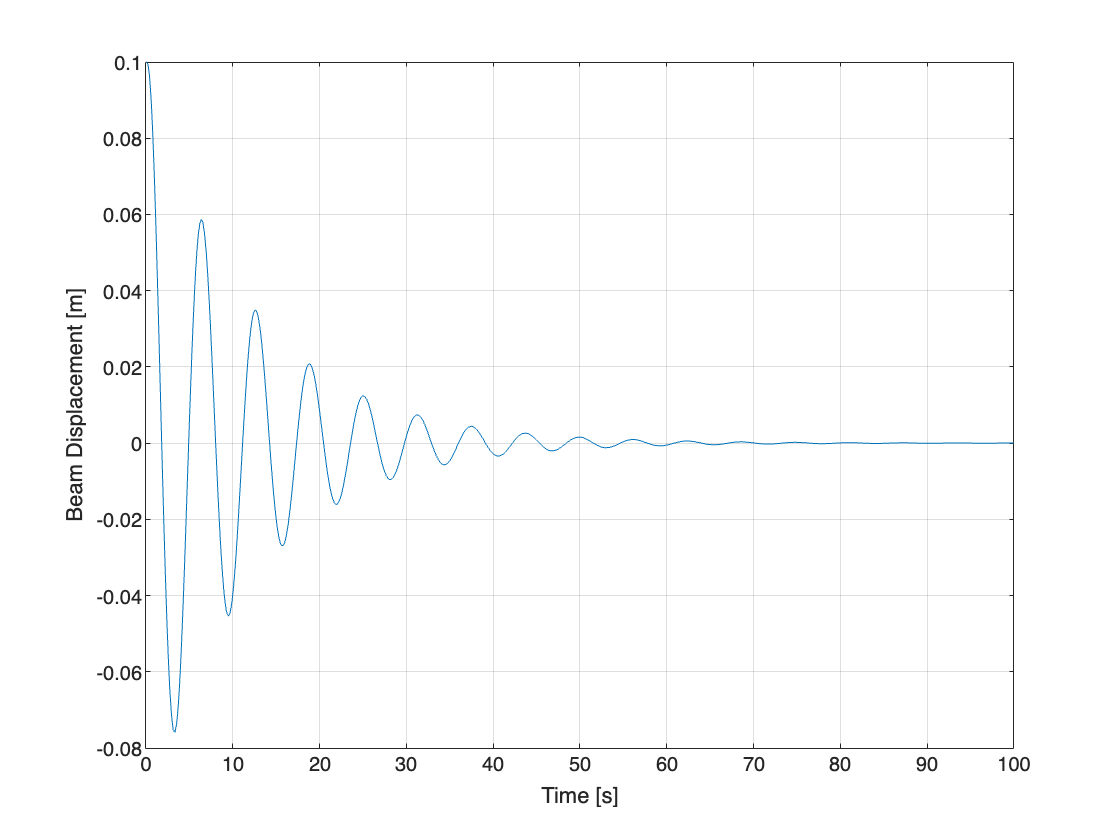

figure
clf
plot(tt, xx(:,1))
xlabel("Time [s]")
ylabel("Beam Displacement [m]")
grid("on")